## Mechanical-Electrical Analogy

机电类比

Analogy: Mass / Spring / Damper  --vs-- Capacitor / Inductor / Resistor

Analogy: force / velocity  --vs--  current / voltage

Across variable (跨量) vs Through variable (通量)

% Copyright 2021 The MathWorks, Inc.

% parameters and I.C.
m = 3.600;     % kg
k = 400;    % N/m
b = 10;      % Ns/m
x0= 1; % m
open_system("ssc_mass_spring_damper_v2")

sim("ssc_mass_spring_damper_v2")

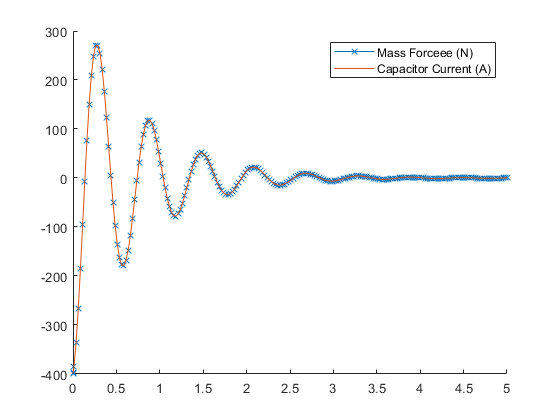

% examine results
time = simlog.Mass.f.series.time;
F_mass = simlog.Mass.f.series.values('N');
I_capacitor = simlog.Capacitor.i.series.values('A');

figure(101); clf;
hold on
plot(time,F_mass,'-x')
plot(time,I_capacitor)
legend("Mass Forceee (N)","Capacitor Current (A)")

*Copyright 2021 The MathWorks, Inc.*